addpath('E:\BaiduSyncdisk\Matlab')
addpath('E:\BaiduSyncdisk\Matlab\VMIE')
addpath('C:\Users\Liushoukang\Desktop\VMIE\src')
addpath('E:\BaiduSyncdisk\Matlab\2DCS-ETC-master\TDCS-ETC\WaveletSoftware\')
addpath('E:\BaiduSyncdisk\Matlab\2DCS-ETC-master\TDCS-ETC\mywork')

tic
P = imread("C:\Users\Liushoukang\Desktop\VMIE\image\Lena512.bmp");pname="Couple512";

P=Imreadforgary(P);

% pt=imshow(P);
%saveFullScreenFigure(pt,pname);

C = imread("C:\Users\Liushoukang\Desktop\VMIE\image\Boat512.bmp");cname="Truck512";
% ct=imshow(C);
%saveFullScreenFigure(ct,cname);

C = Imreadforgary(C);  % carriager image

[H, N] = size(P);
%Step1 Associated with the plain image(Last used)
Pmes = LBP(P,30);
Message = hash(Pmes, 'SHA-256');  %输出为64位的十六进制数
% 初始秘钥
alpha1=1.3;
alpha2=90;
alpha3=-0.9;

m1 = hex2dec(Message(1:4))   + hex2dec(Message(5:8))   + hex2dec(Message(9:12))  + hex2dec(Message(13:16));
m2 = hex2dec(Message(17:20)) + hex2dec(Message(21:24)) + hex2dec(Message(25:28)) + hex2dec(Message(29:32));
m3 = hex2dec(Message(33:36)) + hex2dec(Message(37:40)) + hex2dec(Message(41:44)) + hex2dec(Message(45:48));
m4 = hex2dec(Message(49:52)) + hex2dec(Message(53:56)) + hex2dec(Message(57:60)) + hex2dec(Message(61:64));

c1 = RSA(m1, "encrypt");
c2 = RSA(m2, "encrypt");
c3 = RSA(m3, "encrypt");
c4 = RSA(m4, "encrypt");

%密钥流生成
x0=cos((floor(c1./m1)-c1./m1+alpha1*alpha2)*pi);
y0=cos((floor(c2./m2)-c2./m2+alpha2*alpha3)*pi);
z0=cos((floor(c3./m3)-c3./m3+alpha3*alpha1)*pi);
T = mod(floor(c1./m1)+floor(c2./m2)+floor(c3./m3)+floor(c4./m4)+floor(sin(alpha1*alpha2*alpha3*pi)),1000);
[X,Y,Z]=NewCheyLCM(x0,y0,z0,T,H*N);
t1=toc;
fprintf('密钥流生成时间为 %8.5f',t1)

密钥流生成时间为  1.06302

## 2DCS压缩与加密

tic

CR=0.5;  

Phi1=hadamard(H);
Phi2=hadamard(H);

Rx1=X(1:H*CR);Rx2=X(1:N);
Ry1=Y(1:H*CR);Ry2=Y(1:N);

[~,Rx1Index]=sort(Rx1);
[~,Rx2Index]=sort(Rx2);
[~,Ry1Index]=sort(Ry1);
[~,Ry2Index]=sort(Ry2);

[~,Index]=sort(Z(1:H*N*CR*CR));

Phi1=Phi1(Rx1Index,Rx2Index);
Phi2=Phi2(Ry1Index,Ry2Index);

% Phi1 = orth(randn(H, N))';                   
% 
% Phi1 = Phi1(1:CR*H, :);
%  
% Phi2 = orth(randn(H, N))';                   
% 
% Phi2 = Phi2(1:CR*H, :);


RBI=Quantization(Z,255);

RBI=reshape(S(RBI,H*N),H,N);
 
[Temp,Max,Min]=CS(P,Phi1,Phi2,Index,RBI);

% 由于Temp的鲁棒性很弱，所以要要对Temp的内容名感性进行分散，这样保证对处理过的图像进行攻击对原图像的影响降到最低

Temp1=Scramble(Index,Temp);

Temp2=Diffusion(Temp1,X);

t2=toc;

fprintf('加密时间为 %8.5f',t2)

加密时间为  0.20094

## 压缩加密后的图像

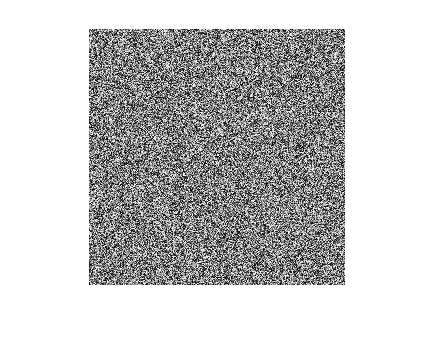

tt=imshow(uint8(Temp2));

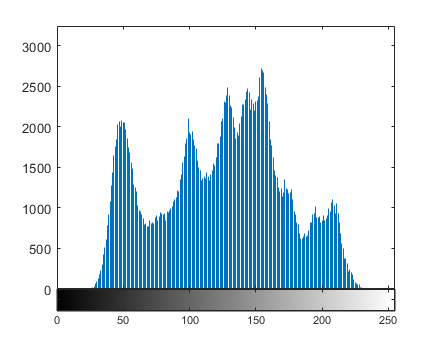

imhist(uint8(P))

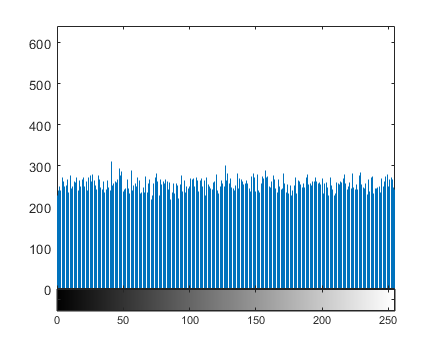

imhist(uint8(Temp2))


%saveFullScreenFigure(tt,"en"+pname);


## 2K校正法嵌入

tic
C1=EmbedofIL2K(double(Temp2),C);
t3=toc;
fprintf('嵌入时间为 %8.5f',t3)

嵌入时间为  0.06031

fprintf('图像隐藏算法总时间为 %8.5f',t1+t2+t3)

图像隐藏算法总时间为  1.32427

## 鲁棒性分析

% C1=imnoise(uint8(C1),"salt & pepper",0.001);
% C1(1:64,1:64)=0;

## 盲提取

tic
Temp_extract=double(ExtractofIL2K(double(C1)));
t1=toc;
fprintf('盲提取时间为 %8.5f',t1)

盲提取时间为  0.01868

## 隐写图像与载体图像对比展示

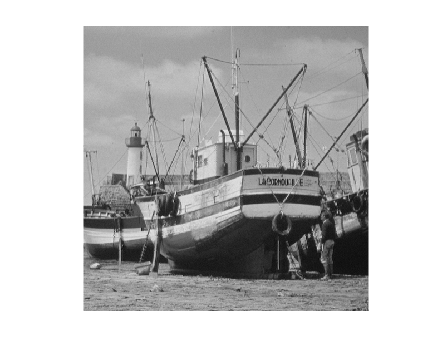

c1t=imshow(uint8(C1));

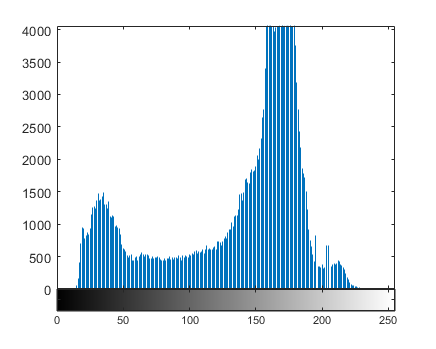

imhist(uint8(C))

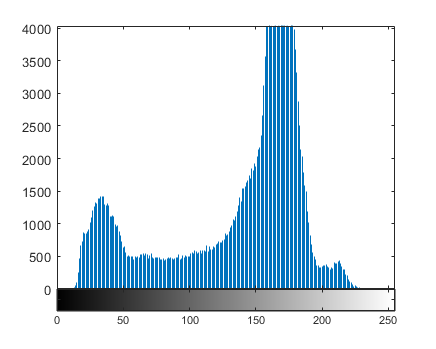

imhist(uint8(C1))

%saveFullScreenFigure(c1t,cname+"C"+pname);
psnr(uint8(C1),uint8(C))

ans = 45.4088

multissim(uint8(C1),uint8(C))

ans = single
0.9978

ssim(uint8(Temp_extract),uint8(Temp2))

ans = 1

## 解密

tic
[X,Y,Z]=NewCheyLCM(x0,y0,z0,T,H*N);

Temp_extract1=IDiffusion(Temp_extract,X);

Temp_extract2=Unscramble(Index,Temp_extract1);

t2=toc;

fprintf('解密时间为 %8.5f',t2)

解密时间为  0.20914

## 重建图像

tic

reconstructed_image=ICS(Temp_extract2,Max,Min,X,Y,Z);

t3=toc;

fprintf('重建时间为 %8.5f',t3)

重建时间为  4.98700

fprintf('图像隐藏恢复总时间为 %8.5f',t1+t2+t3)

图像隐藏恢复总时间为  5.21482

## 重建图像与明文图像对比展示

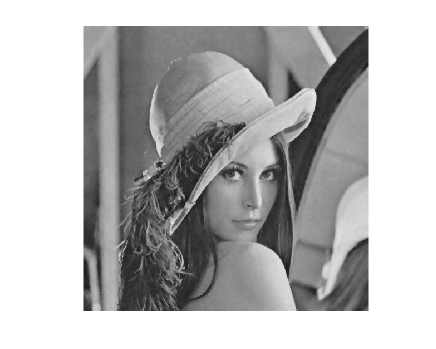

rt=imshow(uint8(reconstructed_image));

%saveFullScreenFigure(rt,"res"+pname+"F"+cname);

## 重建图像与原图数据对比

psnr(uint8(reconstructed_image),uint8(P))

ans = 34.3907

entropy(uint8(P))

ans = 7.4456

entropy(uint8(reconstructed_image))

ans = 7.4166

SUM(P.*reconstructed_image)/(sqrt(SUM(P.^2))*sqrt(SUM(reconstructed_image.^2)))

ans = 0.9993